# Assignment: Vita-Valentino-Linanti 

The code simulates the random walk of a point-source particles surrounded by a sphere medium (R=1) characterized by a certain absorption cross section (sigma_a). The code is based on a Monte Carlo logic and returns as output the probability of leackage of the particle from the spherical shield. After this "first layer" calculation, the Central Limit Theorem verification is carried on to verify if the stopping criteria of the random-walk cycle is sufficient. 

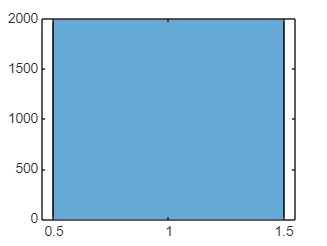

clear  all  
rng(123) % NB: seed of the random algorithm has to fixed


number_of_runs = 50; % set the number of times of mesuring the code required time of calculation 


collapsed_time_base_case=zeros(1,number_of_runs);


for tc=1:length(collapsed_time_base_case) % testing loop

tic  % tracking calculation time starting 


for ii=1:2000

R=1; %radious of the shield 
sigma=0.5; % total micro-cross section of the material (material propriety)
pa=0.2; % probability of absorption
ps=1-pa; % probability of scattering , (pa+ps=1)


err=1; % error initilization 
toll=0.01; % tollerance of the MC code (it is not known a priori if it is enough) 
i=1; % index of the MC loop


while err>toll || i<100
    x0 = 0;
    y0 = 0;
    z0 = 0; % starting position of the particle
    vita = 1; % flag variable for the first while loop (if the particle is alive, thus not absorbed or leaked out it is = 1)
    
    while vita==1
        mu = -1+2*rand; % mu= cos(theta), theta is the polar angle. mu lays inside [0,1], and rand generates random number [0,1]
        phi = 2*pi*rand; % phi is the azimutal angle
        l = -1/sigma*log(rand); % starting potential length of the fly
        
        x = x0+l*cos(phi)*sqrt(1-mu^2); % x position, evaluated with spherical coordinate
        y = y0+l*sin(phi)*sqrt(1-mu^2); % ...
        z = z0+l*mu; % ...
        
        volo=sqrt(x^2+y^2+z^2); % actual length of the fly 
        
        if volo>R % if particle is outside the sphere 
            csi(i)=1; % event counter, if particles leaked out, csi =1 otherwise = 0
            vita=0;   % interrupt while cycle 

        elseif volo<R % if particle stays inside the medium 
                %still in the medium 
                if rand<pa % if particle is absorbed 
                    %particle absorbed 
                    vita=0;
                    csi(i)=0;
                else % if particle is scattered
                    vita=1; % not necessary, just as remark 
                    x0=x;y0=y;z0=z; % new starting position 
                    
                end
        end
        
        
    end
    
    
    samp_av_r(i)=sum(csi)/i; % smaple average
    mom_2_r(i)=sum(csi.^2)/i; % average of csi quadrature 
    var_r(i)=mom_2_r(i)-samp_av_r(i)^2; % variance definition 
    RSD_r(i)=sqrt(var_r(i)/i)/samp_av_r(i); % relative standar deviation definition
    
    err=RSD_r(i); % error = rsd, to be compared with the tollerance
    
    
    i=i+1; % while loop counter

    
end

check_CLT_samp_av(ii)=samp_av_r(end); % colleciton of the sample-average for CLT verification


end

collapsed_time_base_case(tc) = toc; % calculation time recording

clearvars -except collapsed_time_base_case check_CLT_samp_av ii  % clear all variables except the collaction of the times vector 
end

histogram(check_CLT_samp_av) % 

average_computational_time_base_code = sum(collapsed_time_base_case)/length(collapsed_time_base_case)

average_computational_time_base_code = 0.2156

% IMPORVEMENT: parrallelization using parfor (4 workers available)

clear all;
rng(123);
number_of_runs = 50
collapsed_time_opt_case = zeros(number_of_runs,1);


for ttc=1:length(collapsed_time_opt_case)
       
tic
toll = 0.01; 
R = 1;  
sigma = 0.5;
pa = 0.2;
ps = 1 - pa;

parfor ii = 1:2000

    err = 1;
    i = 1;

    samp_av_r = 0;
    var_r = 0;
    RSD_r = 0;
    csi = 0;
    mom_2_r = 0;
    
    while err > toll || i < 100
 
        x0 = 0; y0 = 0; z0 = 0;
        vita = 1;

        while vita == 1
            mu = -1 + 2 * rand;
            phi = 2 * pi * rand;
            l = -1 / sigma * log(rand);

            x = x0 + l * cos(phi) * sqrt(1 - mu^2);
            y = y0 + l * sin(phi) * sqrt(1 - mu^2);
            z = z0 + l * mu;

            volo = sqrt(x^2 + y^2 + z^2);

            if volo > R 
                % Leaked out 
                csi(i) = 1;
                vita = 0;
            elseif volo < R 
                % Still in the medium 
                if rand < pa
                    % Particle absorbed 
                    vita = 0;
                    csi(i) = 0;
                else 
                    vita = 1; % Not necessary, just as a remark 
                    x0 = x; y0 = y; z0 = z;
                end
            end
        end

        samp_av_r(i) = sum(csi) / i;
        mom_2_r(i) = sum(csi.^2) / i;
        var_r(i) = mom_2_r(i) - samp_av_r(i)^2;
        RSD_r(i) = sqrt(var_r(i) / i) / samp_av_r(i);

        err = RSD_r(i);
        i = i + 1;
    end

    check_CLT_samp_av(ii) = samp_av_r(end);


end

collapsed_time_opt_case(ttc) = toc; 

clearvars -except collapsed_time_opt_case

end

%histogram(check_CLT_samp_av)
average_computational_time_opt_code=sum(collapsed_time_opt_case)/length(collapsed_time_opt_case)

average_computational_time_opt_code = 3.8463

% IMPROVEMENT: vector initialization 
clear all; 
rng(123);
number_of_runs
collapsed_time_opt_case = zeros(number_of_runs,1);


for ttc=1:length(collapsed_time_opt_case)
rng(123)        
tic
toll = 0.01; 
R = 1; 
sigma = 0.5;
pa = 0.2;
maxiter = 100;
%ps = 1 - pa; useless variable


% initialize check_CLT_samp_av
check_CLT_samp_av = zeros(1,2000);


parfor ii = 1:2000

    err = 1;
    i = 1;

    % initialize statistic vectors
    samp_av_r = zeros(1,maxiter);
    var_r = zeros(1,maxiter);
    RSD_r = zeros(1,maxiter);
    csi = zeros(1,maxiter);
    mom_2_r = zeros(1,maxiter);

    
    while err > toll || i < maxiter
 
        x0 = 0; y0 = 0; z0 = 0;
        vita = 1;

        while vita == 1
            mu = -1 + 2 * rand;
            phi = 2 * pi * rand;
            l = -1 / sigma * log(rand);

            x = x0 + l * cos(phi) * sqrt(1 - mu^2);
            y = y0 + l * sin(phi) * sqrt(1 - mu^2);
            z = z0 + l * mu;

            volo = sqrt(x^2 + y^2 + z^2);

            if volo > R 
                % Leaked out 
                csi(i) = 1;
                vita = 0;
            elseif volo < R 
                % Still in the medium 
                if rand < pa
                    % Particle absorbed 
                    vita = 0;
                    csi(i) = 0;
                else 
                    vita = 1; % Not necessary, just as a remark 
                    x0 = x; y0 = y; z0 = z;
                end
            end
        end

        samp_av_r(i) = sum(csi) / i;
        mom_2_r(i) = sum(csi.^2) / i;
        var_r(i) = mom_2_r(i) - samp_av_r(i)^2;
        RSD_r(i) = sqrt(var_r(i) / i) / samp_av_r(i);

        err = RSD_r(i);
        i = i + 1;
    end
    last_index = i-1;
    check_CLT_samp_av(ii) = samp_av_r(last_index);

    % Clear variables to reduce memory usage

end

collapsed_time_opt_case(ttc) = toc;
clearvars -except collapsed_time_opt_case

end

%histogram(check_CLT_samp_av)
average_computational_time_opt_code=sum(collapsed_time_opt_case)/length(collapsed_time_opt_case)

average_computational_time_opt_code = 3.8770

% IMPROVEMENT: elimination of the useless vector (remark: the goal is ust
% the verification of the MC simulation accuracy through CLT

clear all
rng(123)    
collapsed_time_opt_case = zeros(50,1);


for ttc=1:length(collapsed_time_opt_case)
tic
toll = 0.01; 
R = 1; % Radius of the shield 
sigma = 0.5;
pa = 0.2;
maxiter = 100;
%ps = 1 - pa; unusefull variable


% initialize check_CLT_samp_av
check_CLT_samp_av = zeros(1,2000);


parfor ii = 1:2000

    err = 1;
    i = 1;

    % initialize statistic vectors
    samp_av_r = zeros(1,maxiter);
    %var_r = zeros(1,maxiter);
    RSD_r = zeros(1,maxiter);
    csi = zeros(1,maxiter);
    %mom_2_r = zeros(1,maxiter);
    %samp_av_r = 0;
    %var_r = 0;
    %RSD_r = 0;
    %csi = 0;
    %mom_2_r = 0;
    
    while err > toll || i < maxiter
 
        x0 = 0; y0 = 0; z0 = 0;
        vita = 1;

        while vita == 1
            mu = -1 + 2 * rand;
            phi = 2 * pi * rand;
            l = -1 / sigma * log(rand);

            x = x0 + l * cos(phi) * sqrt(1 - mu^2);
            y = y0 + l * sin(phi) * sqrt(1 - mu^2);
            z = z0 + l * mu;

            volo = sqrt(x^2 + y^2 + z^2);

            if volo > R 
                % Leaked out 
                csi(i) = 1;
                vita = 0;
            elseif volo < R 
                % Still in the medium 
                if rand < pa
                    % Particle absorbed 
                    vita = 0;
                else 
                    vita = 1; % Not necessary, just as a remark 
                    x0 = x; y0 = y; z0 = z;
                end
            end
        end

        samp_av_r(i) = (sum(csi) / i);
        %var_r(i) = sum(csi.^2) / i - samp_av_r(i)^2;
        RSD_r(i) = sqrt((sum(csi.^2) / i - samp_av_r(i)^2)/ i) / samp_av_r(i);

        err = RSD_r(i);
        i = i + 1;
    end
    last_index = i-1;
    check_CLT_samp_av(ii) = samp_av_r(last_index);

    % Clear variables to reduce memory usage

end

collapsed_time_opt_case(ttc) = toc; 
clearvars -except collapsed_time_opt_case

end

%histogram(check_CLT_samp_av)
average_computational_time_opt_code=sum(collapsed_time_opt_case)/length(collapsed_time_opt_case)

average_computational_time_opt_code = 2.5734

% IMPROVEMENT:  elimination of the useless vector (sample _av_r)
clear all
rng(123)    

collapsed_time_opt_case = zeros(50,1);


for ttc=1:length(collapsed_time_opt_case)
tic
toll = 0.01; 
R = 1; % Radius of the shield 
sigma = 0.5;
pa = 0.2;
maxiter = 100;
%ps = 1 - pa; unusefull variable


% initialize check_CLT_samp_av
check_CLT_samp_av = zeros(1,2000);


parfor ii = 1:2000

    err = 1;
    i = 1;

    % initialize statistic vectors
    %samp_av_r = zeros(1,maxiter);
    %var_r = zeros(1,maxiter);
    RSD_r = zeros(1,maxiter);
    csi = zeros(1,maxiter);
    %mom_2_r = zeros(1,maxiter);
    %samp_av_r = 0;
    %var_r = 0;
    %RSD_r = 0;
    %csi = 0;
    %mom_2_r = 0;
    
    while err > toll || i < maxiter
 
        x0 = 0; y0 = 0; z0 = 0;
        vita = 1;

        while vita == 1
            mu = -1 + 2 * rand;
            phi = 2 * pi * rand;
            l = -1 / sigma * log(rand);

            x = x0 + l * cos(phi) * sqrt(1 - mu^2);
            y = y0 + l * sin(phi) * sqrt(1 - mu^2);
            z = z0 + l * mu;

            volo = sqrt(x^2 + y^2 + z^2);

            if volo > R 
                % Leaked out 
                csi(i) = 1;
                vita = 0;
            elseif volo < R 
                % Still in the medium 
                if rand < pa
                    % Particle absorbed 
                    vita = 0;
                else 
                    vita = 1; % Not necessary, just as a remark 
                    x0 = x; y0 = y; z0 = z;
                end
            end
        end

        %samp_av_r(i) = (sum(csi) / i);
        %var_r(i) = sum(csi.^2) / i - samp_av_r(i)^2;
        RSD_r(i) = sqrt((sum(csi.^2) / i - (sum(csi) / i)^2)/ i) / (sum(csi) / i);

        err = RSD_r(i);
        i = i + 1;
    end

    last_index = i-1;
    check_CLT_samp_av(ii) = (sum(csi) / last_index);


end

collapsed_time_opt_case(ttc) = toc; 
rng(123)    
clearvars -except collapsed_time_opt_case

end

%histogram(check_CLT_samp_av)
average_computational_time_opt_code = sum(collapsed_time_opt_case)/length(collapsed_time_opt_case)

average_computational_time_opt_code = 2.3483

% IMPROVEMENT: elimination of the RSD_r vector
clear all; 
rng(123)    

collapsed_time_opt_case = zeros(50,1);


for ttc=1:length(collapsed_time_opt_case)
tic
toll = 0.01; 
R = 1; % Radius of the shield 
sigma = 0.5;
pa = 0.2;
maxiter = 100;
%ps = 1 - pa; unusefull variable


% initialize check_CLT_samp_av
check_CLT_samp_av = zeros(1,2000);


parfor ii = 1:2000

    err = 1;
    i = 1;

    % initialize statistic vectors
    %samp_av_r = zeros(1,maxiter);
    %var_r = zeros(1,maxiter);
    %RSD_r = zeros(1,maxiter);
    csi = zeros(1,maxiter);
    %mom_2_r = zeros(1,maxiter);
    %samp_av_r = 0;
    %var_r = 0;
    %RSD_r = 0;
    %csi = 0;
    %mom_2_r = 0;
    
    while err > toll || i < maxiter
 
        x0 = 0; y0 = 0; z0 = 0;
        vita = 1;

        while vita == 1
            mu = -1 + 2 * rand;
            phi = 2 * pi * rand;
            l = -1 / sigma * log(rand);

            x = x0 + l * cos(phi) * sqrt(1 - mu^2);
            y = y0 + l * sin(phi) * sqrt(1 - mu^2);
            z = z0 + l * mu;

            volo = sqrt(x^2 + y^2 + z^2);

            if volo > R 
                % Leaked out 
                csi(i) = 1;
                vita = 0;
            elseif volo < R 
                % Still in the medium 
                if rand < pa
                    % Particle absorbed 
                    vita = 0;
                else 
                    vita = 1; % Not necessary, just as a remark 
                    x0 = x; y0 = y; z0 = z;
                end
            end
        end

        %samp_av_r(i) = (sum(csi) / i);
        %var_r(i) = sum(csi.^2) / i - samp_av_r(i)^2;
        RSD_r = sqrt((sum(csi.^2) / i - (sum(csi) / i)^2)/ i) / (sum(csi) / i);

        err = RSD_r;
        i = i + 1;
    end

    last_index = i-1;
    check_CLT_samp_av(ii) = (sum(csi) / last_index);

    % Clear variables to reduce memory usage

end

collapsed_time_opt_case(ttc) = toc; 
clearvars -except collapsed_time_opt_case
    
end

%histogram(check_CLT_samp_av)
average_computational_time_opt_code = sum(collapsed_time_opt_case)/length(collapsed_time_opt_case)

average_computational_time_opt_code = 2.2456